# Main con switching potentials

Configuration space

clear; close all;
grid = Grid(100,10);
grid.setGoal([5,9]);

Obstacles and robot initial configuration

%Caso normale 3 ostacoli
grid.addObstacle(Obstacle(2,4,[1;0]));
grid.addObstacle(Obstacle(10,6,[-1;0]));
grid.addObstacle(Obstacle(2,10,[0.5;-0.5]));

%Problema che sbatte con un raggio h (o di visione) troppo piccolo
% grid.addObstacle(Obstacle(3,5,[1;0]));
% grid.addObstacle(Obstacle(10,6,[-1;0]));
% grid.addObstacle(Obstacle(2,10,[0.5;-0.5]));

%Gli arriva dritto in faccia e deve ingrandire la circonferenza
% grid.addObstacle(Obstacle(5,5,[0;-0.7]));

%Non ci sbatte senza evitarlo
% grid.addObstacle(Obstacle(2,1,[1;0.3]));


% grid.addObstacle(Obstacle(2,2,[1;0.3]));
% grid.addObstacle(Obstacle(2,10,[0.5;-0.5]));

n = length(grid.obstacles);
r = SwitchingRobot(0.15,0.3,grid,0.05);

Inizio simulazione

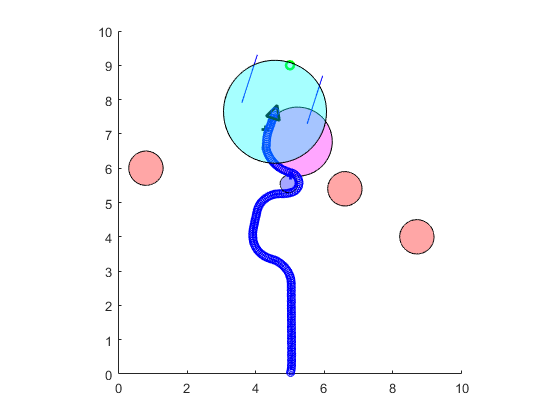

r.start();